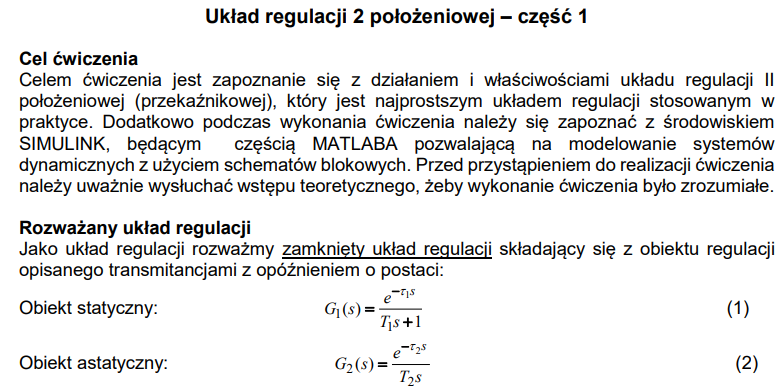

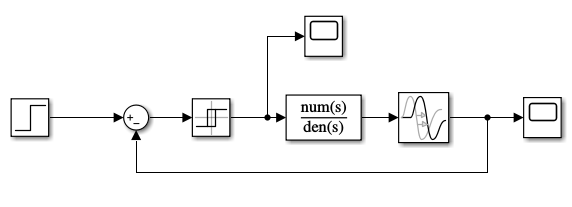

Rys. 1. Układ zbudowany w Simulinku

## Eksperyment 1: Wpływ szerokości histerezy regulatora h

h = 0.05

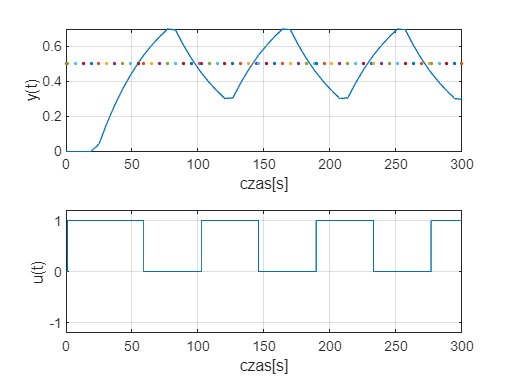

SP = 0.5; h = 0.05; T = 45; tau = 22;
%out1 = out;
draw(out1, SP);

h = 0.1

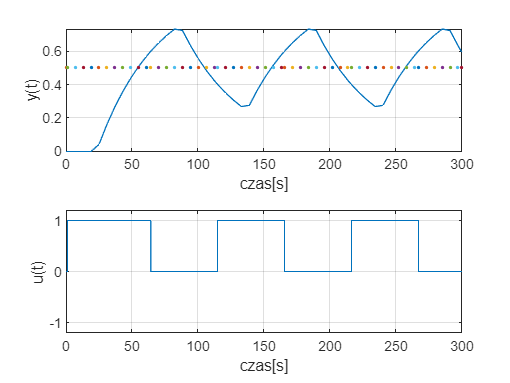

SP = 0.5; h = 0.1; T = 45; tau = 22;
%out2 = out;
draw(out2, SP);

h = 0.2

SP = 0.5; h = 0.2; T = 45; tau = 22;
%out3 = out;
draw(out3, SP);

Wraz ze wzrostem wartości h obserwujemy "rozciąganie się" obu funkcji - wzrost ich okresu (spadek częstotliwości). Im większa histereza, tym radrze przełączenia regulatora i tym większy maksymalny uchyb (amplituda).

## Eksperyment 2:  Wpływ wartości opóźnienia obiektu tau

tau = 10

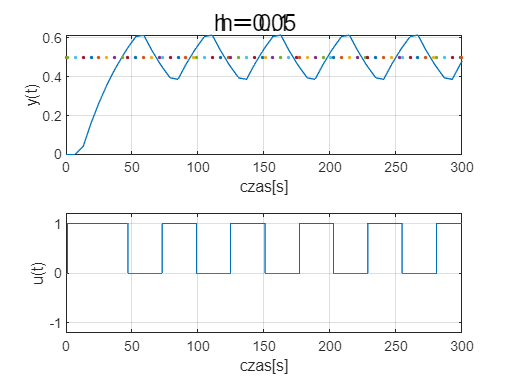

SP = 0.5; h = 0.05; T = 45; tau = 10;
%out21 = out;
draw(out21, SP);

tau = 22

SP = 0.5; h = 0.05; T = 45; tau = 22;
%out22 = out;
draw(out22, SP);

tau = 35

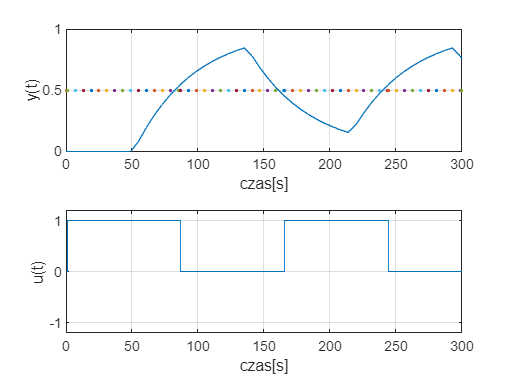

SP = 0.5; h = 0.05; T = 45; tau = 35;
%out23 = out;
draw(out23, SP);

Zwiększanie opóźnienia obiektu, również powoduje zwiększenie uchybu maksymalnego (amplitudy) i spadek częstotliwości

## Eksperyment 3:  Wpływ wartości stałej czasowej obiektu T

T = 25

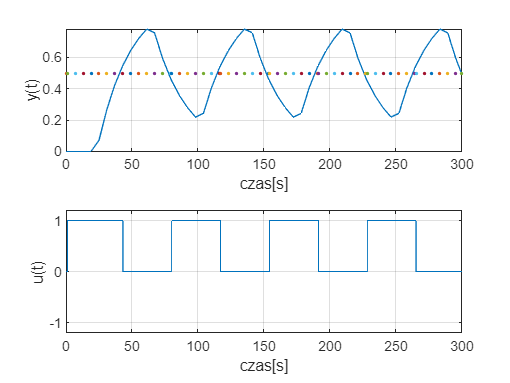

SP = 0.5; h = 0.05; T = 25; tau = 22;
%out31 = out;
draw(out31, SP);

T = 45

SP = 0.5; h = 0.05; T = 45; tau = 22;
%out32 = out;
draw(out32, SP);

T = 60

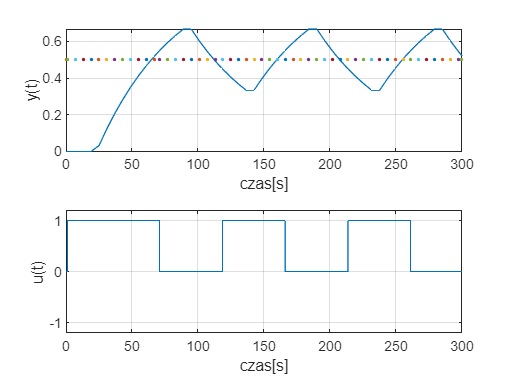

SP = 0.5; h = 0.05; T = 60; tau = 22;
%out33 = out;
draw(out33, SP);

Zwiększanie stałej czasowej obiektu, powoduje zmniejszenie amplitudy y(t) i spadek częstotliwości sygnałów

## Eksperyment 4: Wpływ poziomu wartości zadanej SP

SP = 0.2

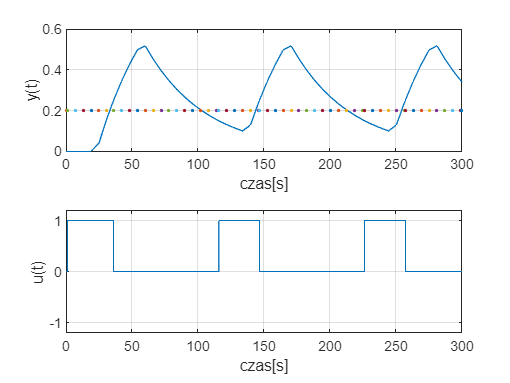

SP = 0.2; h = 0.05; T = 45; tau = 22;
%out41 = out;
draw(out41, SP);

SP = 0.5

SP = 0.5; h = 0.05; T = 45; tau = 22;
%out42 = out;
draw(out42, SP);

SP = 0.9

SP = 0.9; h = 0.05; T = 45; tau = 22;
%out43 = out;
draw(out43, SP);


Kiedy wartość zadana jest mała, jest szybko osiągana przez obiekt, i przez większość czasu regulator jest przełączony, tak że zmniejsza wartość wyjścia - przez większość czasu ma ono wartość, która przekracza wartość zadaną. Układ zachowuje się analogicznie przy dużej wartości SP - wartość rzeczywista przez większość czasu jst poniżej wartości zadanej. Zmiana SP zmniejsza częstotliwość sygnałów.

Obiekt astatyczny potrzebował w bloku Relay wartości Output when off na poziomie -1, ponieważ w przypadku podania wartości 0, sygnał wyjściowy nie dążyłby do zera, a pozostawał na stałym poziomie

## Eksperyment 4: Wpływ poziomu wartości zadanej SP dla obiektu astatycznego

SP = 0.2

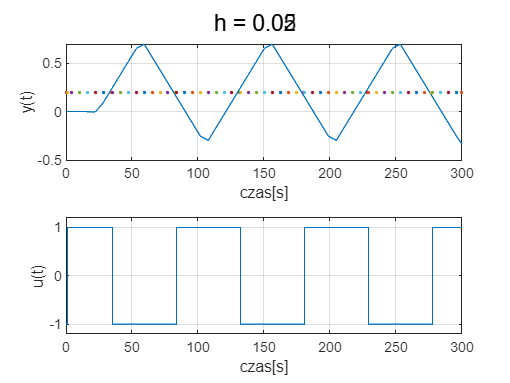

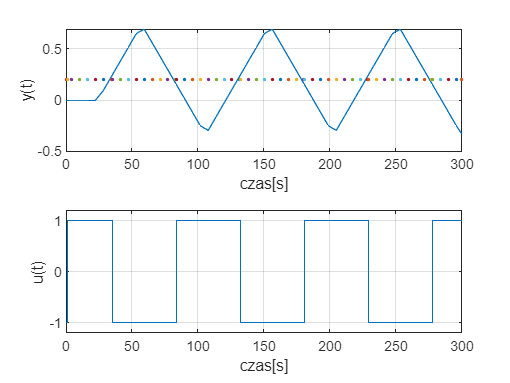

SP = 0.2; h = 0.05; T = 45; tau = 22;
%out51 = out;
draw(out51, SP);

SP = 0.5

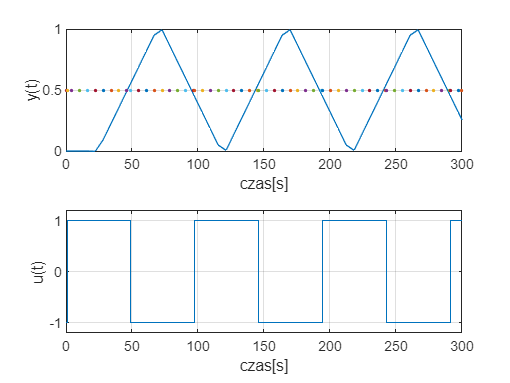

SP = 0.5; h = 0.05; T = 45; tau = 22;
%out52 = out;
draw(out52, SP);

SP = 0.9

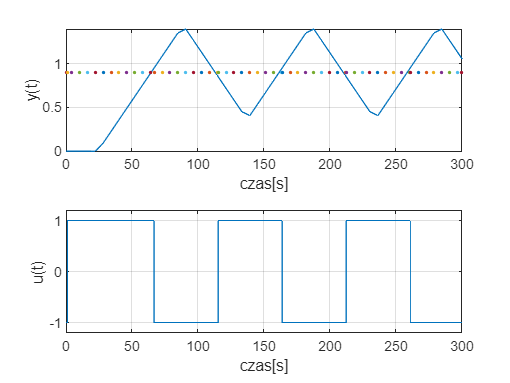

SP = 0.9; h = 0.05; T = 45; tau = 22;
%out53 = out;
draw(out53, SP);

Amplituda w przypadku obiektu astatycznego jest większa niż w przypadku statucznego, natomiast różni się kształt sygnału y(t) - w astatycznym rośnie i spada zakresami liniowo. W przypadku małej wartości SP, sygnal wyjściowy osiąga wartości ujemne.

sgtitle("")

function [] = draw(out, SP)
    figure;
    subplot(2,1,1)
    plot(out.y.time,out.y.signals.values,out.y.time,SP,'.')
    grid
    xlabel('czas[s]')
    ylabel('y(t)')
    subplot(2,1,2)
    plot(out.u.time,out.u.signals.values)
    grid
    xlabel('czas[s]')
    ylabel('u(t)')
    axis([0,300,-1.2,1.2])
end